# Mapeado con posiciones conocidas

## Introducción

Antes de ejecutar este código, debe haberse inicializado el sistema ROS con el script 'conectar.m' y deben haberse creado las subscripciones necesarias para leer los datos de la odometría y del láser (mediante el script 'ini_simulador.m' o 'ini_amigobot.m')

Este ejemplo crea un mapa a partir de un sensor de distancia (láser) y posiciones del robot tomadas como conocidas (odometría).

## Lectura del árbol de transformadas de ROS 

Mediante la función [`rostf`](docid:robotics_ref.bupf5_j_12)`, `podremos acceder al árbol de transformadas de ROS (/tf) para leer de ahí la posición del robot en el momento exacto en que se adquieran los datos del láser.

tftree = rostf;

% Pause for a second for the transformation tree object to finish
% initialization.

pause(1);

## Definición de un mapa (rejilla) vacío

A continuación, crea una variable llamada 'map' (linea 7) utilizando la clase [`robotics.OccupancyGrid`](docid:robotics_ref.bvaw60t-1) para contener un mapa de hasta 25x25 metros, con una resolución de 20 celdas por metro. Después, escribe un valor apropiado para la propiedad GridLocationInWorld (linea 8) de manera que, en función de la posición inicial del robot dentro del entorno, el mapa a obtener quepa bien dentro de la rejilla: 

...
...

Visualizamos el mapa en una figura:

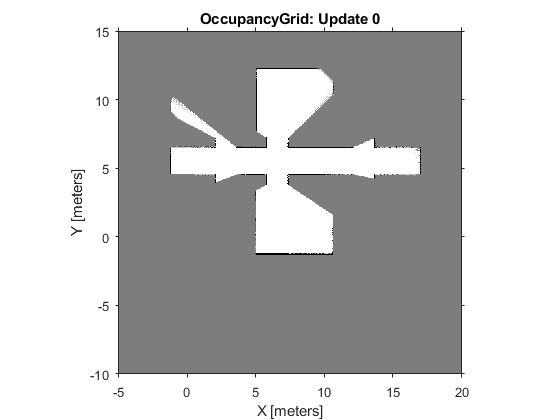

figureHandle = figure('Name', 'Map');
axesHandle = axes('Parent', figureHandle);
mapHandle = show(map, 'Parent', axesHandle);
title(axesHandle, 'OccupancyGrid: Update 0');

## Bucle de creación del mapa

El siguiente bucle irá construyendo el mapa del entorno a medida que el robot se mueva por el mismo (se debe teleoperar el robot mientras tanto). Rellena los pasos indicados del bucle de control, teniendo en cuenta los siguientes aspectos:

- En primer lugar debe obtenerse el último mensaje del láser a través del subscriber correspondiente. Después se debe utilizar [`getTransform`](docid:robotics_ref.buqbijb) , pasando el 'time stamp' del mensaje anterior, para obtener la posición exacta del robot en el momento de la lectura del láser. Se tomará esa posición de la odometría, es decir de la relación entre el frame del robot y el frame de odometría (comprobar sus nombres en ROS mediante el comando 'rqt').

- Obtener la posición y la orientación a partir de la transformada anterior. La orientación del robot es el ángulo yaw entorno al eje z. Éste se puede obtener a partir del cuaternio de posición con la función [`quat2eul`](docid:robotics_ref.buofjpw).

- Extraer las distancias y los ángulos del mensaje del laser. En caso de que se obtenga una medida infinita, sustituirla por la máxima distancia.

- Insertar la observación del laser utilizando el método [`insertRay`](docid:robotics_ref.bvaw7o8-1) de la variable `map`.

- Visualizar el mapa cada 50 actualizaciones del mismo.

updateCounter = 1;
while(1)
    % Lee en msg_laser el último mensaje del láser
    msg_laser = sub_laser.LatestMessage;
    
    % Obtener la posición del robot en el momento de la lectura del laser.
    % Para ello, rellenar correctamente los valores 'target_frame' y
    % 'source_frame' con los nombres correctos de los frames en la
    % siguiente llamada
    pose = getTransform(tftree, '...', '...', msg_laser.Header.Stamp, 'Timeout', 2);
    
    % Convierte la posición del robot a vector [x y yaw]
    position = [pose.Transform.Translation.X, pose.Transform.Translation.Y];
    orientation =  quat2eul([pose.Transform.Rotation.W, pose.Transform.Rotation.X, ...
        pose.Transform.Rotation.Y, pose.Transform.Rotation.Z], 'ZYX');
    robotPose = [position, orientation(1)];
    
    % Extraer los rangos y los ángulos del mensaje del láser.
    ranges = ...
    angles = ...
    ranges(isinf(ranges)) = 8;  %Eliminar datos infinitos
    
    % Insertar la medida del laser en el mapa utilizando 'insertRay',
    % pasandole los datos apropiados obtenidos anteriormente
    insertRay(...);  %Es un método de la clase OccupancyGrid. Consular la ayuda.
    
    % Visualizamos el mapa cada 50 actualizaciones.
    if ~mod(updateCounter,50)
        mapHandle.CData = occupancyMatrix(map);
        title(axesHandle, ['OccupancyGrid: Update ' num2str(updateCounter)]);
    end
    updateCounter = updateCounter+1;
        
    % Wait for control rate to ensure 10 Hz rate
    waitfor(r);
end

Error using robotics.ros.TransformationTree/handleErrorCode (line 545)
Both 'target_frame' and 'source_frame' are invalid frame names in the transformation tree. Use the 'AvailableFrames' property to see all valid frame names.

Error in robotics.ros.TransformationTree/getTransform (

## Dibujar y salvar el mapa obtenido

Para salir del bucle anterior, el usuario deberá finalizar el programa mediante Ctr+C, por lo que se abandonará el script. 

Para dibujar el mapa final obtenido y guardarlo en un fichero 'mi_mapa.mat', ejecutar en linea de comandos las siguientes lineas:

show(map, 'Parent', axesHandle);
title(axesHandle, 'OccupancyGrid: Final Map');

save mi_mapa.mat map